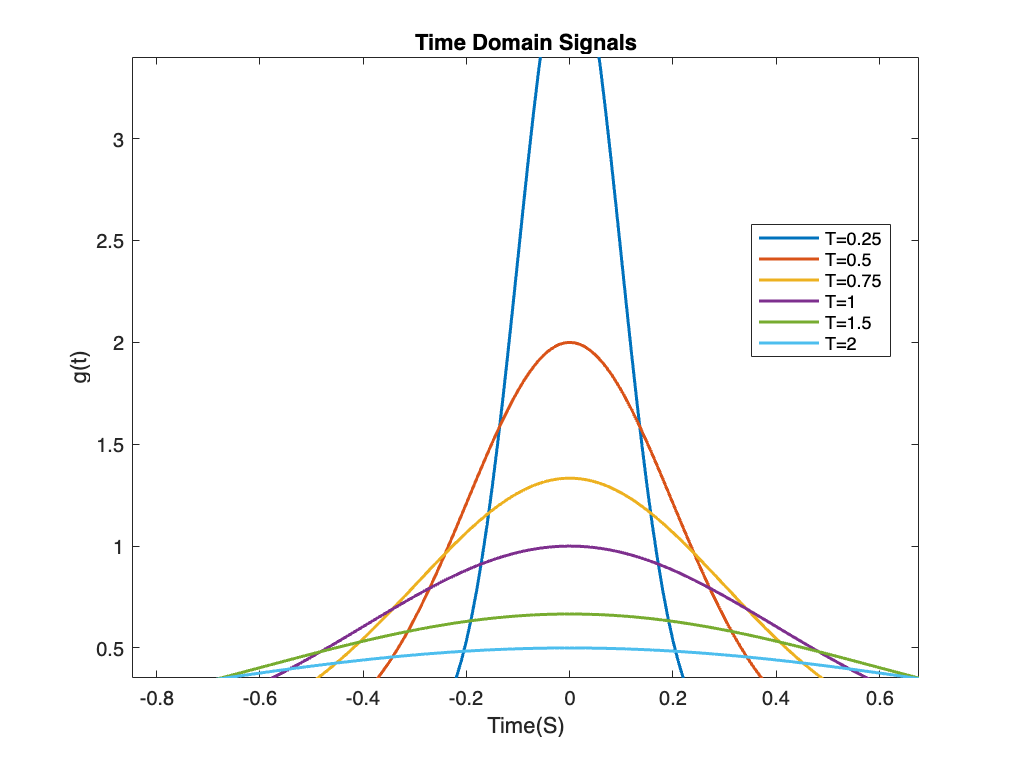

clear all
close all
clc

%Considering the following values for 𝜏
tao = [0.25 0.5 0.75 1 1.5 2];
%time axises from -1 to 1
time = -1:0.01:1;
%Hz axises from -1 to -1
frequency = -1:0.01:1;

%six curves into a graph
%tao column vector 6by1
T = tao(:);
%time domain in a row vector 1by N-amount
t = time(:)';
%Hz in a row vector 1by N-amount
f = frequency(:)';

%Calculating the parameters using the given equations:
%results being 6byN in one row per tau
gt = (1./T) .* exp( (-pi*(t.^2)) ./ (T.^2) );

%G(f) = exp( -pi * tau^2 * f^2 )
gf = exp( -pi * (T.^2) .* (f.^2) );
%Plot time domain graph (Fig. 1)
figure
%plotting all 6 curves on the same axes
plot(t, gt, "LineWidth", 1.5)
title("Time Domain Signals")
xlabel("Time(S)")
ylabel("g(t)")
legend("T=0.25","T=0.5","T=0.75","T=1","T=1.5","T=2","Location","best")

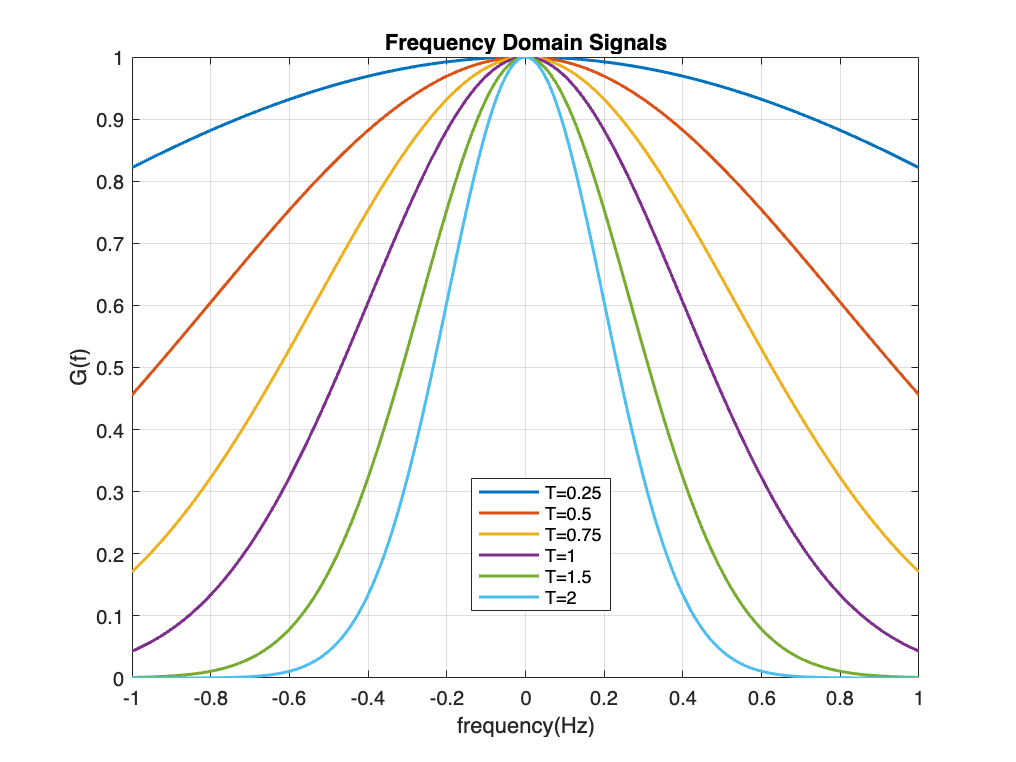


%Plotting frequency domain graph (Fig. 2)
figure
plot(f, gf, "LineWidth", 1.5)
title("Frequency Domain Signals")
xlabel("frequency(Hz)")
ylabel("G(f)")
legend("T=0.25","T=0.5","T=0.75","T=1","T=1.5","T=2","Location","best")
grid on